tic;
clc;
load('rec_2m.mat') % input signal data to 'val' variable
x = val(1,1:5000);
N=length(x);
t=1:N;
tx=t./500;
fs=500;
tic;
y = FFT_DIT(x);
y=fftshift(y);
elapsed_time = toc;
% Display the DFT result
disp('DFT result:');

DFT result:


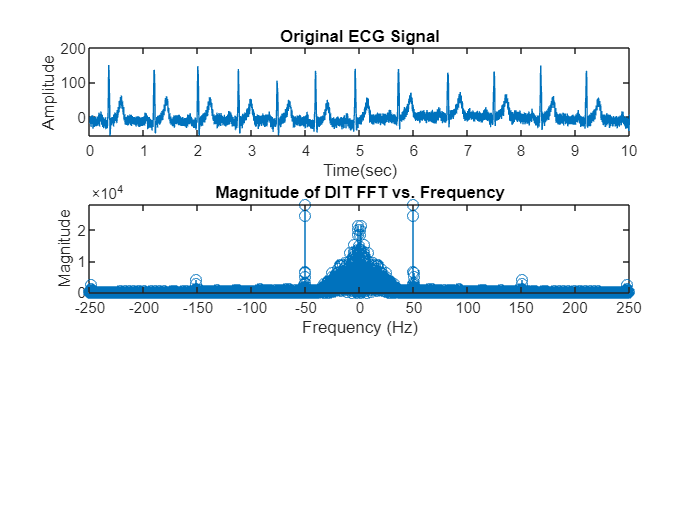

% Plot the original ECG signal 
figure;
subplot(3, 1, 1);
plot(tx,x);
title('Original ECG Signal');
xlabel('Time(sec)');
ylabel('Amplitude');    
% Plot the magnitude of the DFT vs. frequency
subplot(3, 1, 2);
h=length(y);
l=(-h/2:(h/2-1))*(fs/h);
stem(l, abs(y));
title('Magnitude of DIT FFT vs. Frequency');
xlabel('Frequency (Hz)');
ylabel('Magnitude');  

elapsed_time1 = toc;
disp(['DFT Result (Computation Time: ' num2str(elapsed_time) ' seconds):']);

DFT Result (Computation Time: 0.076573 seconds):


disp(['DFT Result (Execution Time: ' num2str(elapsed_time1) ' seconds):']);

DFT Result (Execution Time: 0.3858 seconds):


function [ y ] = FFT_DIT( x )
N=length(x);
nextPow2 = 2^nextpow2(N);
x = [x, zeros(1, nextPow2 - N)];
N = nextPow2;                                                              % computing the array size
S=log2(N);                                                                  % computing the number of conversion stages
Half=1;                                                                     % Seting the initial "Half" value
x=bitrevorder(x);                                                           % Placing the data samples in bit-reversed order
for stage=1:S                                                              % stages of transformation
    for index=0:(2^stage):(N-1)                                            % series of "butterflies" for each stage
        for n=0:(Half-1)                                                   % creating "butterfly" and saving the results
            pos=n+index+1;                                                  % index of the data sample
            pow=(2^(S-stage))*n;                                            % part of power of the complex multiplier
            w=exp((-1i)*(2*pi)*pow/N);                                      % complex multiplier
            a=x(pos)+x(pos+Half).*w;                                        % 1-st part of the "butterfly" creating operation
            b=x(pos)-x(pos+Half).*w;                                        % 2-nd part of the "butterfly" creating operation
            x(pos)=a;                                                       % saving computation of the 1-st part
            x(pos+Half)=b;                                                  % saving computation of the 2-nd part
        end
    end
Half=2*Half;                                                                % computing the next "Half" value
end
y=x;                                                                        % returning the result from function
end